# 兔子问题

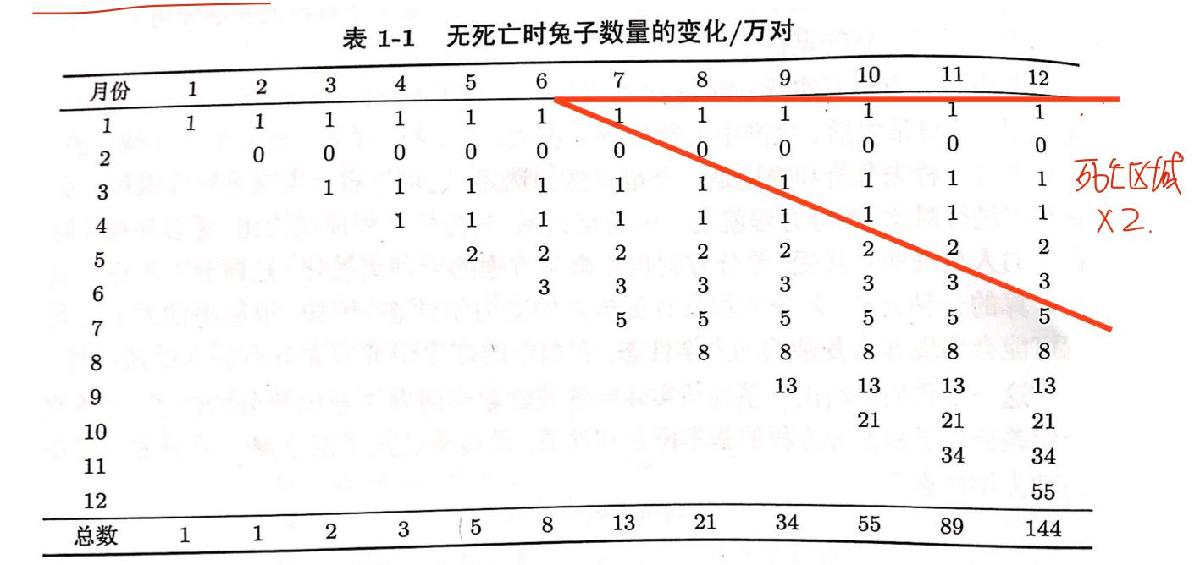

% 兔子死亡相应的也就不能繁殖，则实减去为本身加上繁殖数量即两倍
% 当其n大于7时才会有兔子死亡
% dead ：2 2 4 6 10
%dead(n)=dead(n-1)+dead(n-2)
%dead(1)=dead(2)=2
syms lamda C1 C2
eqn_s=lamda^2-lamda-1==0

$$eqn\_s = {\mathrm{lamda}}^{2}-\mathrm{lamda}-1=0$$

sl=solve(eqn_s)

$$sl = \left(\begin{array}{c} \frac{1}{2}-\frac{\sqrt{5}}{2}\\ \frac{\sqrt{5}}{2}+\frac{1}{2} \end{array}\right)$$

eqn_1=C1*sl(1)+C2*sl(2)==2

$$eqn\_1 = C_{2}\,\left(\frac{\sqrt{5}}{2}+\frac{1}{2}\right)-C_{1}\,\left(\frac{\sqrt{5}}{2}-\frac{1}{2}\right)=2$$

eqn_2=C1*sl(1)^2+C2*sl(2)^2==2

$$eqn\_2 = C_{1}\,{\left(\frac{\sqrt{5}}{2}-\frac{1}{2}\right)}^{2}+C_{2}\,{\left(\frac{\sqrt{5}}{2}+\frac{1}{2}\right)}^{2}=2$$

C=solve(eqn_1,eqn_2)

C = 包含以下字段的 struct :
    C1: -8/((5^(1/2) - 1)*(5^(1/2) + 5))
    C2: (2*(5^(1/2) + 1))/(5^(1/2) + 5)


dead_count=simplify(C.C1*sl(1)^(n-6)+C.C2*sl(2)^(n-6))%日期减6

$$dead\_count = -\frac{\sqrt{5}\,\left(8\,{\left(\frac{1}{2}-\frac{\sqrt{5}}{2}\right)}^{n-6}-8\,{\left(\frac{\sqrt{5}}{2}+\frac{1}{2}\right)}^{n-6}\right)}{20}$$

eqn_3=C1*sl(1)+C2*sl(2)==1

$$eqn\_3 = C_{2}\,\left(\frac{\sqrt{5}}{2}+\frac{1}{2}\right)-C_{1}\,\left(\frac{\sqrt{5}}{2}-\frac{1}{2}\right)=1$$

eqn_4=C1*sl(1)^2+C2*sl(2)^2==1

$$eqn\_4 = C_{1}\,{\left(\frac{\sqrt{5}}{2}-\frac{1}{2}\right)}^{2}+C_{2}\,{\left(\frac{\sqrt{5}}{2}+\frac{1}{2}\right)}^{2}=1$$

sl2=solve(eqn_3,eqn_4)

sl2 = 包含以下字段的 struct :
    C1: -4/((5^(1/2) - 1)*(5^(1/2) + 5))
    C2: (5^(1/2) + 1)/(5^(1/2) + 5)


all_count=simplify(sl2.C1*sl(1)^n+sl2.C2*sl(2)^n)%n<=6时存活数即为总数

$$all\_count = -\frac{\sqrt{5}\,\left(4\,{\left(\frac{1}{2}-\frac{\sqrt{5}}{2}\right)}^{n}-4\,{\left(\frac{\sqrt{5}}{2}+\frac{1}{2}\right)}^{n}\right)}{20}$$

alive_count=simplify(all_count-dead_count)%当n>7时下式成立

$$alive\_count = \frac{17\,\sqrt{5}\,{\left(\frac{1}{2}-\frac{\sqrt{5}}{2}\right)}^{n}}{5}-\frac{17\,\sqrt{5}\,{\left(\frac{\sqrt{5}}{2}+\frac{1}{2}\right)}^{n}}{5}+8\,{\left(\frac{1}{2}-\frac{\sqrt{5}}{2}\right)}^{n}+8\,{\left(\frac{\sqrt{5}}{2}+\frac{1}{2}\right)}^{n}$$

# 2.三角形重心

x=[]


x =

     []



%给定三角型初始三个点
x(1)=1+1i*1;
x(2)=2+1i*4;
x(3)=3+1i*3

x =    1.0000 + 1.0000i   2.0000 + 4.0000i   3.0000 + 3.0000i


%迭代公式


$$A_n ={\frac{\left(A_{n-1} +A_{n-2} +A_{n-3} \right)}{3}}$$


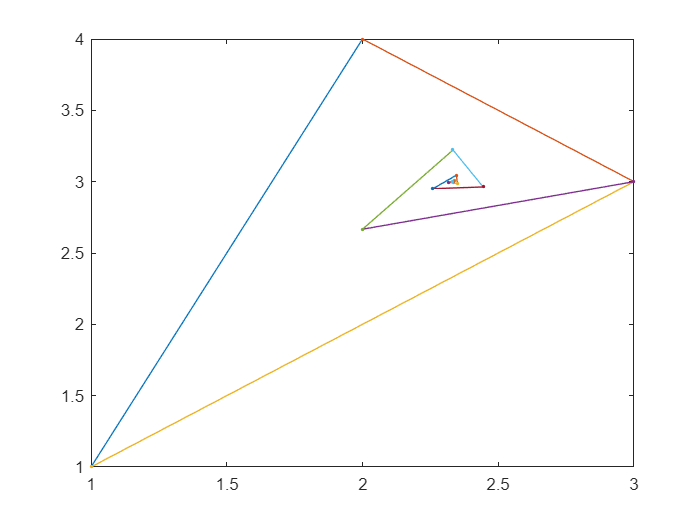

for i=4:1000
    x(i)=(x(i-1)+x(i-2)+x(i-3))/3;
end
tri=[x;x(2),x(3),x(1),x(3:end-1)];
plot(tri,'.-')

% a(i+1)+2*a(i+2)+3*a(i+3)为固定值


$$3A_{n+1}=A_{n}+A_{n-1}+A_{n-2}\\
3A_{n+2}=A_{n+1}+A_{n}+A_{n-1}\\
3A_{n+3}=A_{n+2}+A_{n+1}+A_{n}\\
3A_{n+1}+3A_{n+2}+3A_{n+3}=A_{n+2}+2A_{n+1}+3A_{n}+2A_{n-1}+A_{n-2}\\
==\\
A_{n+1}+2A_{n+2}+3A_{n+3}=A_{n-2}+2A_{n-1}+3A_{n}
$$


for i=1:200
    x(3*i+1)+2.*x(3*i+2)+3.*x(3*i+3);
end

syms lamda
eqn=3*lamda^4-lamda^3-lamda^2-lamda==0

$$eqn = 3\,{\mathrm{lamda}}^{4}-{\mathrm{lamda}}^{3}-{\mathrm{lamda}}^{2}-\mathrm{lamda}=0$$

y=solve(eqn)

$$y = \left(\begin{array}{c} 0\\ 1\\ -\frac{1}{3}-\frac{\sqrt{2}\,\mathrm{i}}{3}\\ -\frac{1}{3}+\frac{\sqrt{2}\,\mathrm{i}}{3} \end{array}\right)$$

w1=y(2)

$$w1 = 1$$

w2=y(3)

$$w2 = -\frac{1}{3}-\frac{\sqrt{2}\,\mathrm{i}}{3}$$

w3=y(4)

$$w3 = -\frac{1}{3}+\frac{\sqrt{2}\,\mathrm{i}}{3}$$

syms c1 c2 c3
eq1=c1*w1+c2*w2+c3*w3==x(1)

$$eq1 = c_{1}-c_{2}\,\left(\frac{1}{3}+\frac{\sqrt{2}\,\mathrm{i}}{3}\right)+c_{3}\,\left(-\frac{1}{3}+\frac{\sqrt{2}\,\mathrm{i}}{3}\right)=1+\mathrm{i}$$

eq2=c1*w1^2+c2*w2^2+c3*w3^2==x(2)

$$eq2 = c_{1}+c_{2}\,{\left(\frac{1}{3}+\frac{\sqrt{2}\,\mathrm{i}}{3}\right)}^{2}+c_{3}\,{\left(-\frac{1}{3}+\frac{\sqrt{2}\,\mathrm{i}}{3}\right)}^{2}=2+4\,\mathrm{i}$$

eq3=c1*w1^3+c2*w2^3+c3*w3^3==x(3)

$$eq3 = c_{1}-c_{2}\,{\left(\frac{1}{3}+\frac{\sqrt{2}\,\mathrm{i}}{3}\right)}^{3}+c_{3}\,{\left(-\frac{1}{3}+\frac{\sqrt{2}\,\mathrm{i}}{3}\right)}^{3}=3+3\,\mathrm{i}$$

solve(eq1,eq2,eq3)%带入初始的三个值，解出相关系数

ans = 包含以下字段的 struct :
    c1: 7/3 + 3i
    c2: (9*(2^(1/2)*2i + 1 + 3i))/(2*(2 + 2^(1/2)*5i))
    c3: (2^(1/2)*(2^(1/2)*(3 - 11i) + 1 + 15i)*1i)/12


# 3.生物生长问题


$$L(t+1)=bA(t)\\
P(t+1)=(1-\mu_L)L(t)\\
A(t+1)=(1-\mu_p)P(t)+(1-\mu_A)A(t)\\
=>\\

A(t+1)=(1-\mu_p)(1-\mu_L)bA(t-2)+(1-\mu_A)A(t)$$


syms mup muL muA b t
eqn_2=t^4-(1-mup)*(1-muL)*b*t-(1-muA)*t^3==0

$$eqn\_2 = t^{4}+\left(\mathrm{muA}-1\right)\,t^{3}-b\,\left(\mathrm{muL}-1\right)\,\left(\mathrm{mup}-1\right)\,t=0$$

solve(eqn_2,t)

$$ans = \begin{array}{l} \left(\begin{array}{c} 0\\ \mathrm{root}\left(\sigma_{1},z,1\right)\\ \mathrm{root}\left(\sigma_{1},z,2\right)\\ \mathrm{root}\left(\sigma_{1},z,3\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=z^{3}+z^{2}\,\left(\mathrm{muA}-1\right)-b\,\mathrm{muL}\,\mathrm{mup}-b+b\,\mathrm{mup}+b\,\mathrm{muL} \end{array}$$

%给出参数,解得数据

# 4.药物

迭代方程为


$$X_n ={\left(1-K\right)X}_{n-1} +A_0$$


syms K A_0 X
eqn_3=X^2-(1-K)*X-A_0==0

$$eqn\_3 = X^{2}+\left(K-1\right)\,X-A_{0}=0$$

sol3=solve(eqn_3,X)

$$sol3 = \left(\begin{array}{c} \frac{1}{2}-\frac{\sqrt{K^{2}-2\,K+4\,A_{0}+1}}{2}-\frac{K}{2}\\ \frac{\sqrt{K^{2}-2\,K+4\,A_{0}+1}}{2}-\frac{K}{2}+\frac{1}{2} \end{array}\right)$$

由药物的浓度迭代公式


$$X_n =\left(1-K\right)X_{k-1} +A_0$$


设其有t^n的解，则t=1-K，$X_n ={A\left(1-K\right)}^n$

则有$A=A_0$

又$X_n \mathrm{极限B}$


$$B=(1-K)B+A_0
$$



$$\begin{array}{l}
B=\frac{A_0 }{K}\\
X_n ={A\left(1-K\right)}^n +\frac{A_0 }{K}\\
A_0 =A+\frac{A_0 }{K}\\
A=\left(1-\frac{1}{K}\right)A_0 \\
X_n =\left(1-\frac{1}{K}\right)A_0 {\left(1-K\right)}^n +\frac{A_0 }{K}
\end{array}$$


即为通项

# 5.hanoi塔

%x(n)=2*x(n-1)+1